folderPath = 'C:\Users\vithj\OneDrive\Documents\Visual Studio Code\AI ML\cw-data-cat\U09'; 

if ~isfolder(folderPath)
    error('The specified folder does not exist: %s', folderPath);
end

fileList = dir(fullfile(folderPath, '*.mat'));  

if isempty(fileList)
    error('No .mat files found in the specified folder: %s', folderPath);
end

fileNames = {fileList.name};  
nFiles = numel(fileNames);    

disp('List of .mat files found for User 01:');

List of .mat files found for User 01:


disp(fileNames);

    {'U09_Acc_FreqD_FDay.mat'}    {'U09_Acc_FreqD_MDay.mat'}    {'U09_Acc_TimeD_FDay.mat'}    {'U09_Acc_TimeD_FreqD_FDay.mat'}    {'U09_Acc_TimeD_FreqD_MDay.mat'}    {'U09_Acc_TimeD_MDay.mat'}



Processing file: U09_Acc_FreqD_FDay.mat


Fields in the current file:


    {'Acc_FD_Feat_Vec'}



Analyzing field: Acc_FD_Feat_Vec


Minimum value: -0.111818


Maximum value: 1.141889


Mean value: 0.129994


Standard deviation: 0.273733


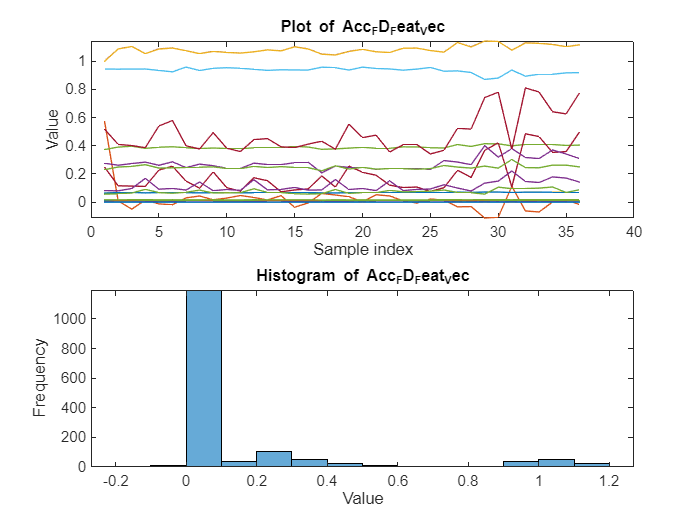

Processing file: U09_Acc_FreqD_MDay.mat


Fields in the current file:


    {'Acc_FD_Feat_Vec'}



Analyzing field: Acc_FD_Feat_Vec


Minimum value: -0.117465


Maximum value: 1.146457


Mean value: 0.136405


Standard deviation: 0.279853


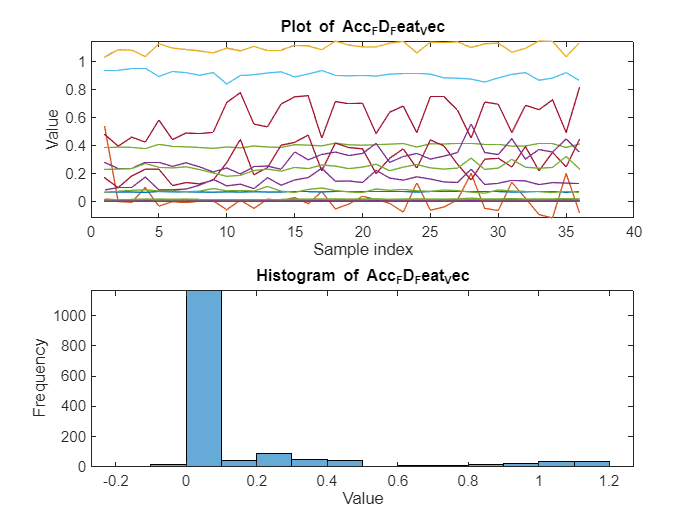

Processing file: U09_Acc_TimeD_FDay.mat


Fields in the current file:


    {'Acc_TD_Feat_Vec'}



Analyzing field: Acc_TD_Feat_Vec


Minimum value: -1.667385


Maximum value: 225.000000


Mean value: 11.854315


Standard deviation: 34.619443


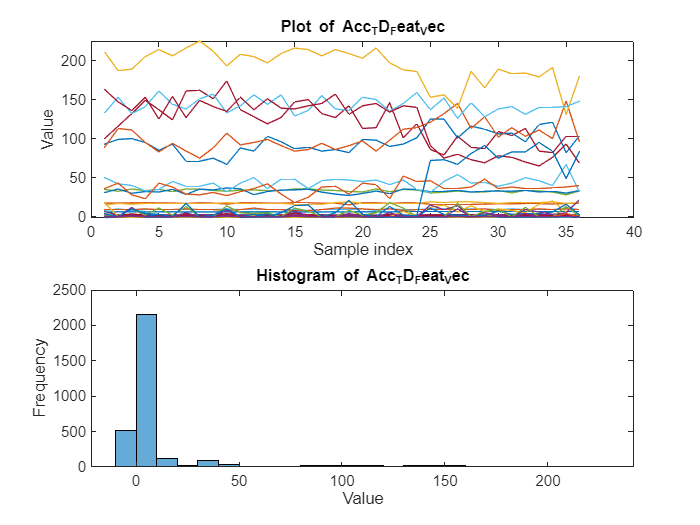

Processing file: U09_Acc_TimeD_FreqD_FDay.mat


Fields in the current file:


    {'Acc_TDFD_Feat_Vec'}



Analyzing field: Acc_TDFD_Feat_Vec


Minimum value: -1.667385


Maximum value: 225.000000


Mean value: 8.005874


Standard deviation: 28.902606


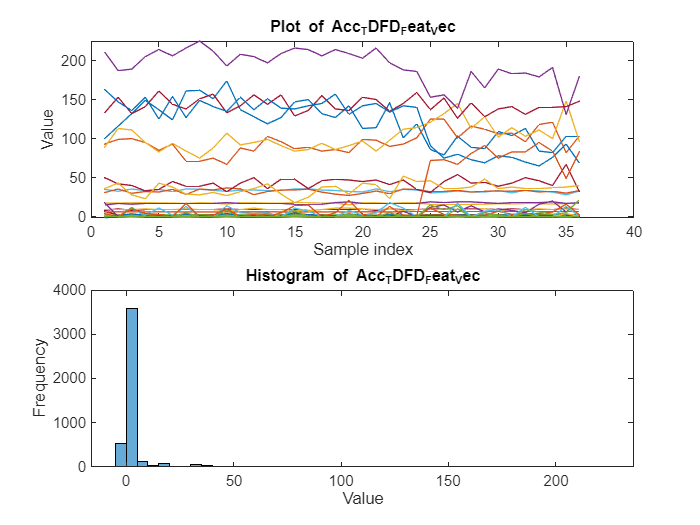

Processing file: U09_Acc_TimeD_FreqD_MDay.mat


Fields in the current file:


    {'Acc_TDFD_Feat_Vec'}



Analyzing field: Acc_TDFD_Feat_Vec


Minimum value: -1.609826


Maximum value: 241.000000


Mean value: 8.020039


Standard deviation: 27.712645


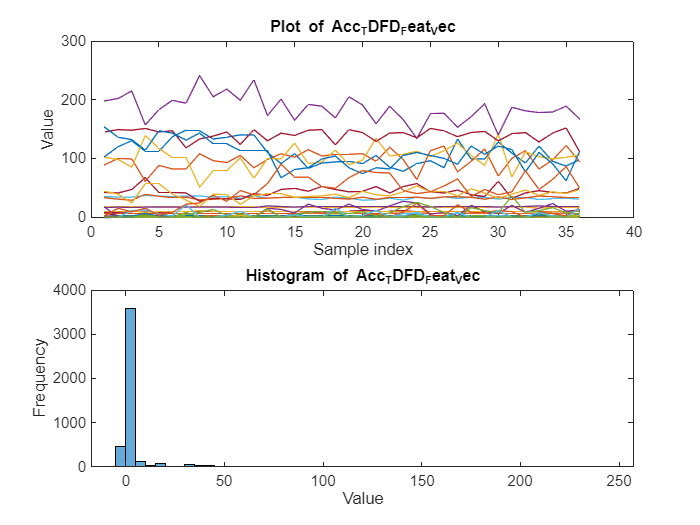

Processing file: U09_Acc_TimeD_MDay.mat


Fields in the current file:


    {'Acc_TD_Feat_Vec'}



Analyzing field: Acc_TD_Feat_Vec


Minimum value: -1.609826


Maximum value: 241.000000


Mean value: 11.872269


Standard deviation: 33.137827


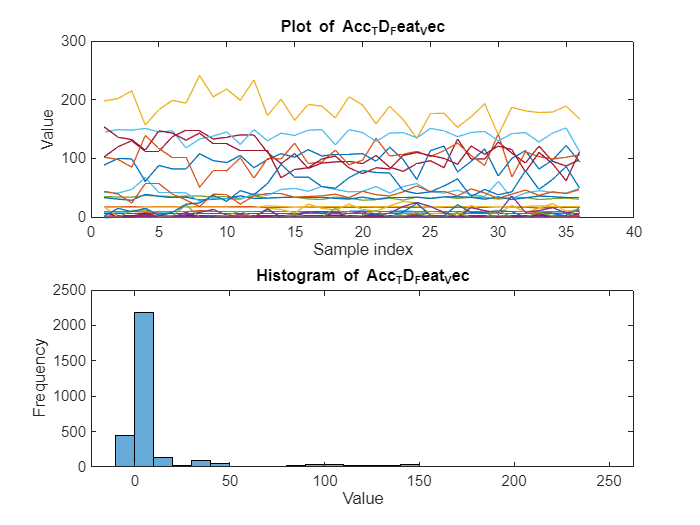


for i = 1:nFiles
    filePath = fullfile(folderPath, fileNames{i});
    
    if exist(filePath, 'file') == 2
        data = load(filePath);  
        fprintf('Processing file: %s\n', fileNames{i});
        
        fields = fieldnames(data);  
        
        disp('Fields in the current file:');
        disp(fields);
       
        for j = 1:length(fields)
            fieldData = data.(fields{j}); 
            
            fprintf('Analyzing field: %s\n', fields{j});
            fprintf('Minimum value: %f\n', min(fieldData(:)));
            fprintf('Maximum value: %f\n', max(fieldData(:)));
            fprintf('Mean value: %f\n', mean(fieldData(:)));
            fprintf('Standard deviation: %f\n', std(fieldData(:)));
            
            figure;  
            subplot(2, 1, 1); 
            plot(fieldData);  
            title(['Plot of ' fields{j}]);
            xlabel('Sample index');
            ylabel('Value');
            
            subplot(2, 1, 2);  
            histogram(fieldData); 
            title(['Histogram of ' fields{j}]);
            xlabel('Value');
            ylabel('Frequency');
        end
    else
        warning('File does not exist: %s', filePath);
    end
end